# Designing Analog Filters	

## **Q: What is a Fourier transform?	**

**Answer:** A fourier transform converts a signal from time-domain to freqency-domain, the transform shows the given signal's frequency components.	

## **Q: What does the Fourier transform of 'noise_signal' show?**

Use Fourier transforms to find the frequency components of a signal buried in noise.

Specify the parameters of a signal with a sampling frequency of 1 kHz and a signal duration of 1.5 seconds.

dt = 0.001;           % Signal dt
Fs = 1/dt;            % Sampling Frequency                    
t = 0:dt:(10-dt);     % Time vector
N = size(t,2);        % Signal length
[y,y_clean] = lab03_signal (t);

Plot the noisy signal in the time domain. It is difficult to identify the frequency components by looking at the signal `X(t)`. 

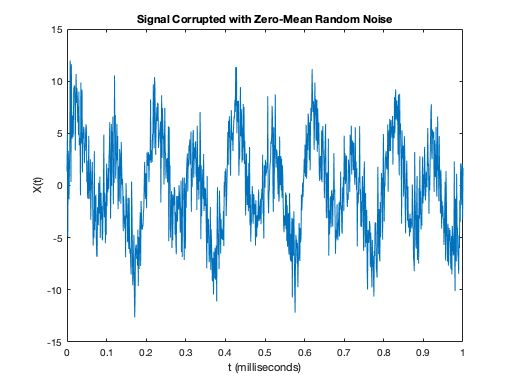

plot(t,y); xlim([0,1])
title('Signal Corrupted with Zero-Mean Random Noise')
xlabel('t (milliseconds)')
ylabel('X(t)')

Compute the Fourier transform of the signal. 

Y = fft(y);

Plot the Frequency plot of the Fourier Transform

P2 = abs(Y/N); % 2-sided spectrum = P2
P1 = P2(1:N/2+1); %Single-sided spectrum from P2 
P1(2:end-1) = 2*P1(2:end-1);


Define the frequency domain f and plot the single-sided amplitude spectrum P1. 

f = Fs*(0:(N/2))/N;
plot(f,P1) 
title('Single-Sided Amplitude Spectrum of Input Signal with Noise.')
xlabel('f (Hz)')
ylabel('|P1(f)|')

Zoom to get a better view: 

**Answer:** The fourier transform of the given signal shows that frequency content of  "Lab03_signal" include a sinusoid at 5Hz and a sinusoid at 10Hz frequency.

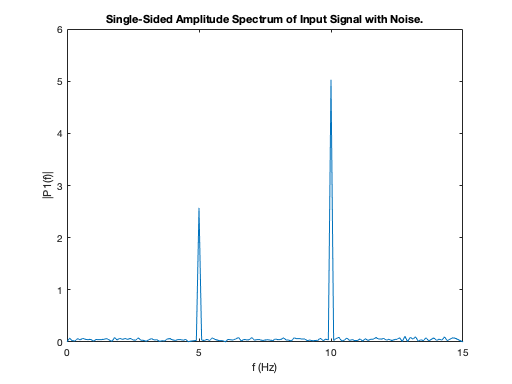

xlim([0,15])

## **Desired output for both Butterworth & Chevyshev Type 1 Filters**

Pass cut-off Frequency: 12.5 Hz

Wp = 12.5*2*pi; % 2*pi = Radians conversion

Stop cut-off Frequency: 15 Hz

Ws = 15*2*pi; 

Pass-ripple : 0.5 dB

Rp = 0.5; 

Minimum Attenuation: 20dB

Rs = 20;


## **Task: Design a Butterworth filter with a cut-off frequency of 12.5 Hz and a minimum attenuation of 20dB at 15 Hz, with a pass ripple of <0.5 dB. Examine the order, zeros and pole of the transfer function as well as the attenuation (or filter gain) from 0 to 50hz (on a linear frequency scale)**

The Lowest order of **Digital **Butterworth Filter needed for the given specifications: 

[n, wn]= buttord(Wp,Ws,Rp,Rs,'s')

n = 19

wn = 83.5131

The order of the butterworth filter to have a  passband ripple of no more 0.5 dB and a stopband attenuation of at least 20dB is 19, which is quite large and is never implemented in practice. 

### Digital Butterworth Filter Transfer Function:

[b,a] = butter(n,wn,'s'); % Will give you the b = Numerator of the TF, a = Denominator of TF
G_butterworth = tf(b,a)


G_butterworth =
 
                  
          3.261e36
                  
  ------------------------
                          
  s^19 + 1011 s^18        
                          
          + 5.114e05 s^17 
                          
          + 1.716e08 s^16 
                          
          + 4.278e10 s^15 
                          
          + 8.413e12 s^14 
                          
          + 1.352e15 s^13 
                          
          + 1.815e17 s^12 
                          
          + 2.066e19 s^11 
                          
          + 2.011e21 s^10 
                          
          + 1.679e23 s^9  
                          
          + 1.204e25 s^8  
                          
          + 7.374e26 s^7  
                          
          + 3.83e28 s^6   
                          
          + 1.662e30 s^5  
                          
          + 5.896e31 s^4  
                          
          + 1.649e33 s^3  
                          
      

### Frequency response of the Butterworth Analog Filter

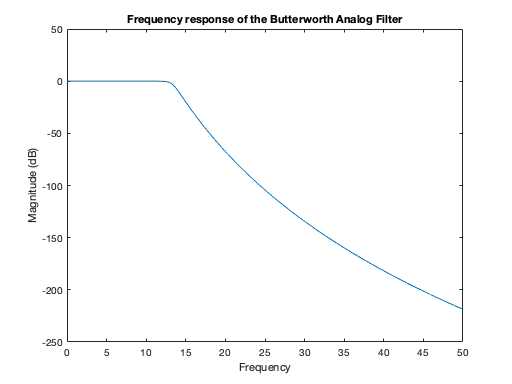

fplot =0:0.01:50; % Create vector for the frequencies from 0-50 Hz
h1=freqs(b,a,2*pi*fplot); % Use freqs to plot the analog filter's response
plot(fplot,mag2db(abs(h1))); 
xlabel("Frequency"); ylabel("Magnitude (dB)");
title("Frequency response of the Butterworth Analog Filter");

### Filter Response:

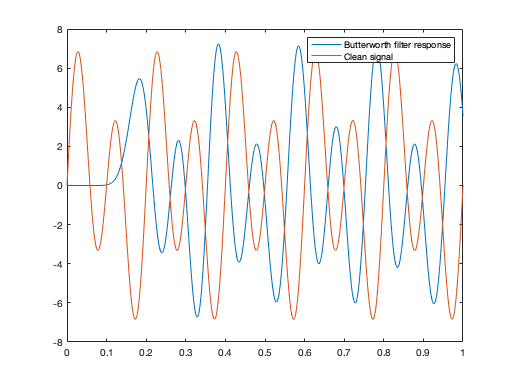

Y_butterworth = lsim(G_butterworth,y,t);

% Plot filter response and y_clean on the same axi
plot(t,Y_butterworth,t,y_clean); xlim([0,1]);
legend("Butterworth filter response","Clean signal")

Comparison between the filter response and the actual clean signal(which was given to compare the filter output with the actual clean signal) show that: 

- There is a slight increase in amplitude for each peak of the filtered output as compared to the clean signal. 

- There is also delay created by the butterworth filter, this can be seen by the time shift in the filtered output in comparison to the original clean signal.

## **Task: Design a Chebyshev Type I filter with a pass frequency of 12.5 Hz and a minimum attenuation of 20dB at 15 Hz, with a pass ripple of <0.5 dB. Examine the order, zeros and pole of the transfer function as well as the attenuation (or filter gain) from 0 to 10hz (on a linear frequency scale) [Use ‘cheb1ord'].	**

The Lowest order of **Digital **Chebyshev Type 1 Filter needed for the given specifications: 

[n,wp]=cheb1ord(Wp, Ws, Rp, Rs,'s')

n = 7

wp = 78.5398

The order of the butterworth filter to have a  passband ripple of no more 0.5 dB and a stopband attenuation of at least 20dB is 7, which is not as high has Butterworth filter and can be implemented. 

### Digital Chevyshev Type 1 Filter Transfer Function:

[b2,a2] = cheby1(n,Rp,wp,'s'); % Will give you the b2 = Numerator of the TF, a2 = Denominator of TF
G_chevyshev = tf(b2,a2)


G_chevyshev =
 
                 
         8.246e11
                 
  -----------------------
                         
  s^7 + 90.42 s^6        
                         
          + 1.488e04 s^5 
                         
          + 9.057e05 s^4 
                         
          + 6.27e07 s^3  
                         
          + 2.258e09 s^2 
                         
          + 6.621e10 s   
                         
              + 8.246e11 
                         
 
Continuous-time transfer function.



### Frequency response of the Chevyshev Type 1 Analog Filter

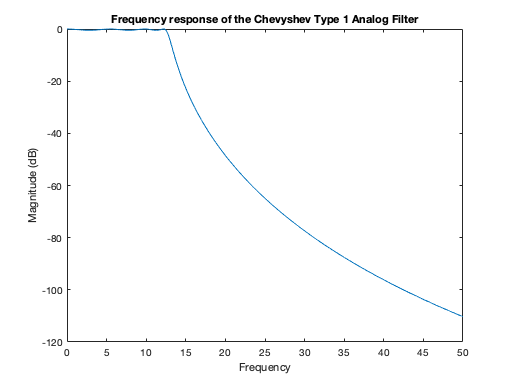

fplot =0:0.01:50; % Create vector for the frequencies from 0-50 Hz
h2=freqs(b2,a2,2*pi*fplot); % Use freqs to plot the analog filter's response
plot(fplot,mag2db(abs(h2))); 
xlabel("Frequency"); ylabel("Magnitude (dB)");
title("Frequency response of the Chevyshev Type 1 Analog Filter");

### Filter Response:

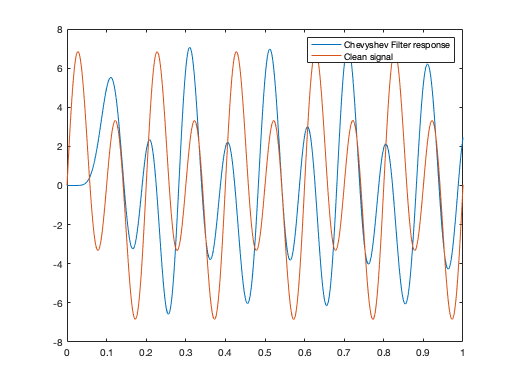

Y_chevyshev = lsim(G_chevyshev,y,t);

% Plot filter response and y_clean on the same axi
plot(t,Y_chevyshev,t,y_clean); xlim([0,1]);
legend("Chevyshev Filter response","Clean signal")

Comparison between the filter response and the actual clean signal(which was given to compare the filter output with the actual clean signal) show that: 

- There is a slight increase in amplitude for each peak of the filtered output as compared to the clean signal. 

- There is a slight delay created by the chevyshev filter(not as much as the delay created by Butterworth filter), this can be seen by the time shift in the filtered output in comparison to the original clean signal.

## **Task: Compare Filter Responses **

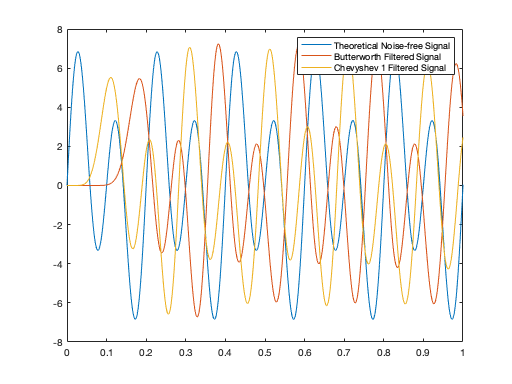

plot(t, y_clean,t,Y_butterworth,t,Y_chevyshev); xlim([0,1]);
legend("Theoretical Noise-free Signal","Butterworth Filtered Signal","Chevyshev 1 Filtered Signal")

The order of the chevyshev type 1 filter required  is lower than the order of the butterworth filter required to achieve a passband ripple of no more 0.5 dB and a stopband attenuation of at least 20dB . They both seem to give almost the same filtered response when you look at the amplitude of the filter response. The difference is that with the Chevyshev type 1 filter you will get the same attenuation faster as compared to butterworth filter. 

## Comparing the Frequency Responses of the Filters

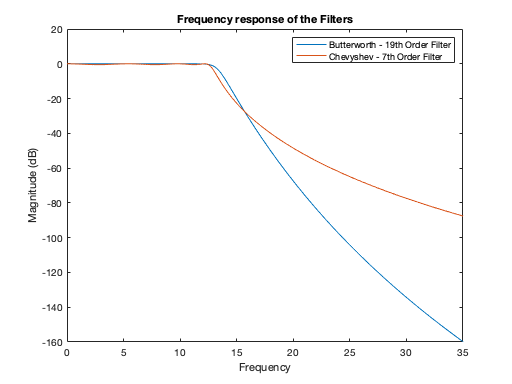

plot(fplot,mag2db(abs(h1)),fplot,mag2db(abs(h2))); 
xlabel("Frequency"); ylabel("Magnitude (dB)"); xlim([0,35]);
title("Frequency response of the Filters");
legend("Butterworth - 19th Order Filter", "Chevyshev - 7th Order Filter")

The Chebyshev achieves a faster roll-off by allowing ripple in the frequency response. As the ripple increases (which is bad), the roll-off becomes sharper (which is good). 

By observing the tthe frequency responses of the two filters, it can be noted that compared to a Butterworth filter, a Chebyshev filter can achieve a sharper transition between the passband and the stopband with a lower order filter. The sharp transition between the passband and the stopband of a Chebyshev filter produces smaller absolute errors and faster execution speeds than a Butterworth filter.

## Comparing Bode Plots of the two Filters

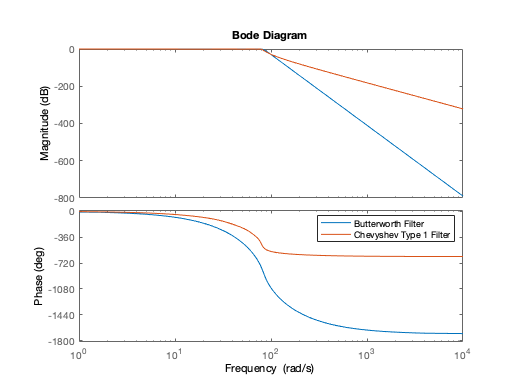

bode(G_butterworth,G_chevyshev);
legend("Butterworth Filter", "Chevyshev Type 1 Filter")

Observations:

- The magnitude plot shows that Butterworth has a better roll-off rate as its steeper than the Chevyshev filter. 

- The Phase plot shows the phase error introduced by the two filters. Both filters introduce phase error around the input signal frequency (at 10*2*pi = 63 rad/s) as shown in the phase plot. Also, the delay created by the butterworth filter is more and this is seen in the time-plot of butterworth filter response in the previous sections.  

A way to minimize the destruction of the input signal, increase the range between the pass and stop frequency, this will allow more low frequencies to pass through and will reduce the phase error introduced by the filter. The increase in gap between pass and stop frequency reduces the roll-off rate of the filter, which reduces the destruction of the input signal. Although, the increase in gap between the pass and stop frequency reduces the destruction of the input signal (by reducing the phase error introduced by the filter), it also allows more noise to pass through the filter, reducing the effectiveness of the filter. Therefore, with analog filters there is a tradeoff, if you want to reduce the input signal destruction then you will have to accept some noise in the filtered signal. 

## Fourier Transform of the Input Signal, Clean Signal & Filter Responses

### Compute the Fourier transform of the Input Signal(with noise)

InputSignalFFT = fft(y);

Plot the Frequency plot of the Fourier Transform

P2 = abs(InputSignalFFT/N); % 2-sided spectrum = P2
P1 = P2(1:N/2+1); %Single-sided spectrum from P2 
P1(2:end-1) = 2*P1(2:end-1);

Define the frequency domain f and plot the single-sided amplitude spectrum P1. 

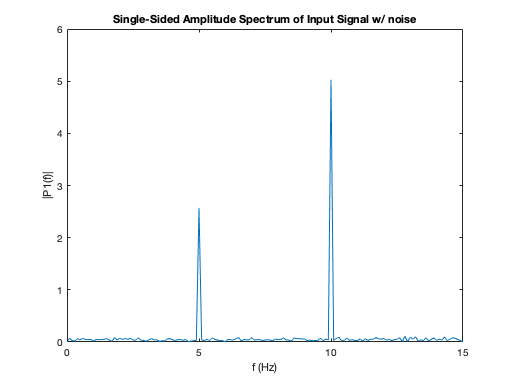

f = Fs*(0:(N/2))/N;
plot(f,P1) 
title('Single-Sided Amplitude Spectrum of Input Signal w/ noise')
xlabel('f (Hz)')
ylabel('|P1(f)|')
xlim([0,15])

### Compute the Fourier transform of the Theoretical Noise-Free signal (Y_clean)

CleanSignalFFT = fft(y_clean);

Plot the Frequency plot of the Fourier Transform

P2 = abs(CleanSignalFFT/N); % 2-sided spectrum = P2
P1 = P2(1:N/2+1); %Single-sided spectrum from P2 
P1(2:end-1) = 2*P1(2:end-1);

Define the frequency domain f and plot the single-sided amplitude spectrum P1. 

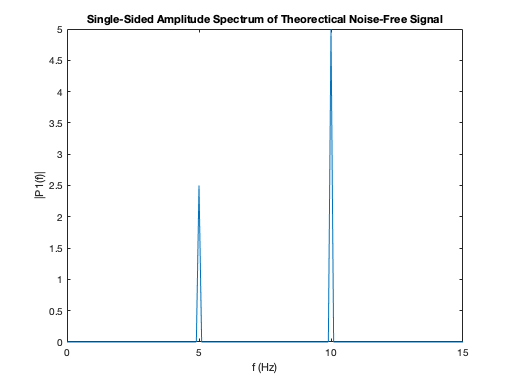

f = Fs*(0:(N/2))/N;
plot(f,P1) 
title('Single-Sided Amplitude Spectrum of Theorectical Noise-Free Signal')
xlabel('f (Hz)')
ylabel('|P1(f)|')
xlim([0,15])

### Compute the Fourier transform of the Butterworth Filtered signal. 

ButterworthResponseFFT = fft(Y_butterworth);

Plot the Frequency plot of the Fourier Transform

P2 = abs(ButterworthResponseFFT/N); % 2-sided spectrum = P2
P1 = P2(1:N/2+1); %Single-sided spectrum from P2 
P1(2:end-1) = 2*P1(2:end-1);

Define the frequency domain f and plot the single-sided amplitude spectrum P1. 

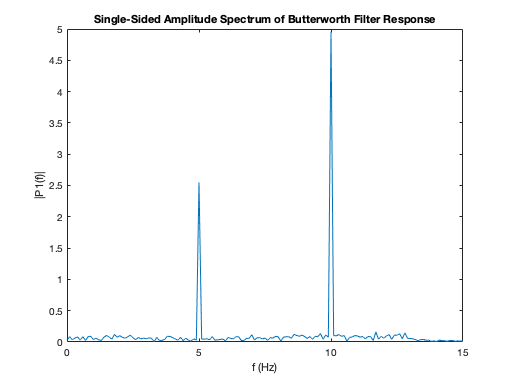

f = Fs*(0:(N/2))/N;
plot(f,P1) 
title('Single-Sided Amplitude Spectrum of Butterworth Filter Response')
xlabel('f (Hz)')
ylabel('|P1(f)|')
xlim([0,15])

### Compute the Fourier transform of the Chevyshev Filtered signal. 

ChevyshevResponseFFT = fft(Y_chevyshev);

Plot the Frequency plot of the Fourier Transform

P2 = abs(ChevyshevResponseFFT/N); % 2-sided spectrum = P2
P1 = P2(1:N/2+1); %Single-sided spectrum from P2 
P1(2:end-1) = 2*P1(2:end-1);

Define the frequency domain f and plot the single-sided amplitude spectrum P1. 

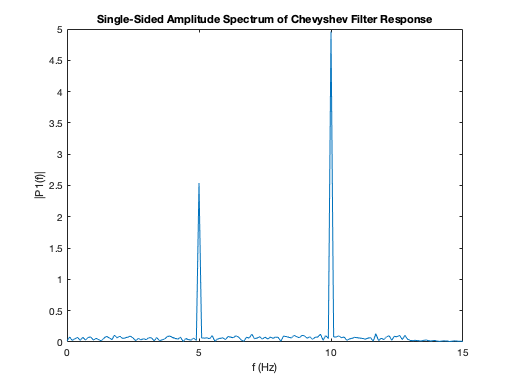

f = Fs*(0:(N/2))/N;
plot(f,P1) 
title('Single-Sided Amplitude Spectrum of Chevyshev Filter Response')
xlabel('f (Hz)')
ylabel('|P1(f)|')
xlim([0,15])